clear all;   %清除workspace中所有变量
clc;       %清除command window中所有命令 
close all;   %清除所有图形

a = 5;
b = 9;
c = 1;

A = [a-b 0.5-c; 0 1];
B = [0; 1];
C = eye(2);
D = zeros(2,1);
k = [-12 0];


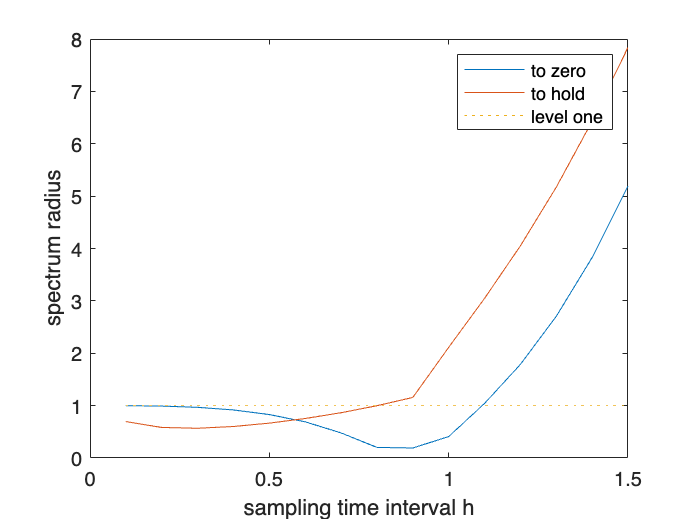

% question 1

h = 0.1:0.1:1.5;
spectral_radius = ones(3,size(h,2)); %to zero; to hold

for j = 1:size(h,2) %to zero
    sys = ss(A,B,[1 1],0);
    sysd = c2d(sys, h(j));
    matrix = sysd.A*(sysd.A-sysd.B*k)^2;
    spectral_radius(1,j) = max(abs(eig(matrix)));
end

for j = 1:size(h,2) %to hold
    sys = ss(A,B,[1 1],0);
    sysd = c2d(sys, h(j));
    sysd2 = c2d(sys, 2*h(j));
    matrix = (sysd2.A-sysd2.B*k)*(sysd.A-sysd.B*k);
    spectral_radius(2,j) = max(abs(eig(matrix)));
end

plot(h,spectral_radius(1:2,:),h,spectral_radius(3,:),':');
legend('to zero','to hold','level one');
xlabel('sampling time interval h');  % 设置 x 轴标签
ylabel('spectrum radius');  % 设置 y 轴标签

% question 2

h = 0.1:0.1:1.5;
spectral_radius2 = zeros(2,size(h,2)); %to zero; to hold


%to zero
for j = 1:size(h,2) %to zero
    sys = ss(A,B,[1 1],0);
    sysd = c2d(sys, h(j));
    matrix1 = sysd.A*(sysd.A-sysd.B*k)^2; %001
    matrix2 = (sysd.A-sysd.B*k)^3; % 000
    eps = 0.0001;
    P = sdpvar(2,2);
    cons = [P>=eye(2)*eps,...
            (P-matrix1'*P*matrix1)>=eye(2)*eps,...
            (P-matrix2'*P*matrix2)>=eye(2)*eps];
    obj = 0;
    result = optimize(cons,obj);
    if result.problem==0
        spectral_radius2(1,j) = 1;
    end
    
end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3, order n = 7, dim = 13, blocks = 4
nnz(A) = 21 + 0, nnz(ADA) = 9, nnz(L) = 6
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.44E+02 0.000
  1 :   0.00E+00 1.07E+01 0.000 0.0738 0.9900 0.9900   1.00  1  1  2.3E+00
  2 :   0.00E+00 2.21E+00 0.000 0.2075 0.9000 0.9000   0.99  1  1  4.7E-01
  3 :   0.00E+00 4.17E-01 0.000 0.1886 0.9000 0.9000   0.98  1  1  9.1E-02
  4 :   0.00E+00 3.53E-02 0.000 0.0848 0.9900 0.9900   0.93  1  1  8.1E-03
  5 :   0.00E+00 6.44E-03 0.000 0.1821 0.9000 0.9000   0.72  1  1  1.8E-03
  6 :   0.00E+00 1.24E-03 0.000 0.1921 0.9000 0.9000   0.87  1  1  3.6E-04
  7 :   0.00E+00 1.22E-04 0.000 0.0989 0.9900 0.9900   0.98  1  1  3.6E-05
  8 :   0.00E+00 1.17E-05 0.000 0.0954 0.9900 0.9900   1.00  1  1  3.4E-06
  9 :   0.00E+00 1.10E-06 0.000 0.0944 0.9900 0.9900   1.00  1  1  3.2E-07
 10 :   0.00E+00 1.0



%to hold
for j = 1:size(h,2)
    sys = ss(A,B,[1 1],0);
    sysd = c2d(sys, h(j));
    sysd2 = c2d(sys, 2*h(j));
    matrix1 = (sysd2.A-sysd2.B*k)*(sysd.A-sysd.B*k); %001
    matrix2 = (sysd.A-sysd.B*k)^3; %000
    eps = 0.00001;
    P = sdpvar(2,2);
    cons = [P>=eye(2)*eps,...
            (P-matrix1'*P*matrix1)>=eye(2)*eps,...
            (P-matrix2'*P*matrix2)>=eye(2)*eps];
    obj = 0;
    result = optimize(cons,obj);
    if result.problem==0
        spectral_radius2(2,j) = 1;
    end
    
end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3, order n = 7, dim = 13, blocks = 4
nnz(A) = 21 + 0, nnz(ADA) = 9, nnz(L) = 6
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.37E+02 0.000
  1 :   0.00E+00 1.77E+01 0.000 0.0748 0.9900 0.9900   1.00  1  1  3.0E+00
  2 :   0.00E+00 5.49E+00 0.000 0.3096 0.9000 0.9000   1.00  1  1  9.2E-01
  3 :   0.00E+00 3.51E-01 0.000 0.0640 0.9900 0.9900   1.00  1  1  5.9E-02
  4 :   0.00E+00 9.85E-02 0.000 0.2804 0.9000 0.9000   1.00  1  1  1.7E-02
  5 :   0.00E+00 2.58E-02 0.000 0.2617 0.9000 0.9000   1.00  1  1  4.3E-03
  6 :   0.00E+00 6.41E-03 0.000 0.2490 0.9000 0.9000   1.00  1  1  1.1E-03
  7 :   0.00E+00 1.54E-03 0.000 0.2396 0.9000 0.9000   1.00  1  1  2.6E-04
  8 :   0.00E+00 3.57E-04 0.000 0.2322 0.9000 0.9000   1.00  1  1  6.0E-05
  9 :   0.00E+00 8.07E-05 0.000 0.2261 0.9000 0.9000   1.00  1  1  1.4E-05
 10 :   0.00E+00 1.7

% question 3

P = [0    0    0.99 0.01   0    0;...
     0    0    0.99 0.01   0    0;...
     0    0    0    0      0.49 0.51;...
     0    0    0    0      0.49 0.51;...
     0.99 0.01 0    0      0    0;...
     0.99 0.01 0    0      0    0];

h = 0.1:0.1:1.5;
spectral_radius3 = zeros(2,size(h,2)); %to zero; to hold

%to zero
for j = 1:size(h,2) %to zero
    sys = ss(A,B,[1 1],0);
    sysd = c2d(sys, h(j));
    A1 = sysd.A; % 1
    A0 = sysd.A-sysd.B*k; % 0
    eps = 0.0001;
    P1 = sdpvar(2,2);
    P2 = sdpvar(2,2);
    P3 = sdpvar(2,2);
    P4 = sdpvar(2,2);
    P5 = sdpvar(2,2);
    P6 = sdpvar(2,2);
    cons = [P1>=eye(2)*eps,P2>=eye(2)*eps,P3>=eye(2)*eps,...
            P4>=eye(2)*eps,P5>=eye(2)*eps,P6>=eye(2)*eps,...
            P1-0.99*A0'*P3*A0-0.01*A1'*P4*A1>=eye(2)*eps,...
            P2-0.99*A0'*P3*A0-0.01*A1'*P4*A1>=eye(2)*eps,...
            P3-0.49*A0'*P5*A0-0.51*A1'*P6*A1>=eye(2)*eps,...
            P4-0.49*A0'*P5*A0-0.51*A1'*P6*A1>=eye(2)*eps,...
            P5-0.99*A0'*P1*A0-0.01*A1'*P2*A1>=eye(2)*eps,...
            P6-0.99*A0'*P1*A0-0.01*A1'*P2*A1>=eye(2)*eps];
    obj = 0;
    result = optimize(cons,obj);
    if result.problem==0
        spectral_radius3(1,j) = 1;
    end
    
end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 18, order n = 25, dim = 49, blocks = 13
nnz(A) = 126 + 0, nnz(ADA) = 324, nnz(L) = 171
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.11E+00 0.000
  1 :   0.00E+00 1.00E+00 0.000 0.2431 0.9000 0.9000   1.00  1  1  2.2E+00
  2 :   0.00E+00 2.16E-01 0.000 0.2155 0.9000 0.9000   0.99  1  1  4.8E-01
  3 :   0.00E+00 4.71E-02 0.000 0.2184 0.9000 0.9000   0.97  1  1  1.1E-01
  4 :   0.00E+00 1.13E-02 0.000 0.2397 0.9000 0.9000   0.91  1  1  2.7E-02
  5 :   0.00E+00 5.54E-04 0.000 0.0491 0.9900 0.9900   0.97  1  1  1.3E-03
  6 :   0.00E+00 3.38E-05 0.000 0.0610 0.9900 0.9900   1.00  1  1  8.2E-05
  7 :   0.00E+00 2.08E-06 0.000 0.0617 0.9900 0.9900   1.00  1  1  5.1E-06
  8 :   0.00E+00 1.28E-07 0.000 0.0615 0.9900 0.9900   1.00  1  1  3.1E-07
  9 :   0.00E+00 7.86E-09 0.000 0.0613 0.9900 0.9900   1.00  1  1  1.9E-08
 10 :   0.00




%to hold
for j = 1:size(h,2) %to hold
    sys = ss(A,B,[1 1],0);
    sysd = c2d(sys, h(j));
    A1 = [sysd.A sysd.B;0 0 1]; % 1
    A0 = [sysd.A [0;0];0 0 0]-[sysd.B; 1]*[k 0]; % 0
    eps = 0.0001;
    P1 = sdpvar(3,3);
    P2 = sdpvar(3,3);
    P3 = sdpvar(3,3);
    P4 = sdpvar(3,3);
    P5 = sdpvar(3,3);
    P6 = sdpvar(3,3);
    cons = [P1>=eye(3)*eps,P2>=eye(3)*eps,P3>=eye(3)*eps,...
            P4>=eye(3)*eps,P5>=eye(3)*eps,P6>=eye(3)*eps,...
            P1-0.99*A0'*P3*A0-0.01*A1'*P4*A1>=eye(3)*eps,...
            P2-0.99*A0'*P3*A0-0.01*A1'*P4*A1>=eye(3)*eps,...
            P3-0.49*A0'*P5*A0-0.51*A1'*P6*A1>=eye(3)*eps,...
            P4-0.49*A0'*P5*A0-0.51*A1'*P6*A1>=eye(3)*eps,...
            P5-0.99*A0'*P1*A0-0.01*A1'*P2*A1>=eye(3)*eps,...
            P6-0.99*A0'*P1*A0-0.01*A1'*P2*A1>=eye(3)*eps];
    obj = 0;
    result = optimize(cons,obj);
    if result.problem==0
        spectral_radius3(2,j) = 1;
    end
    
end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 36, order n = 37, dim = 109, blocks = 13
nnz(A) = 276 + 0, nnz(ADA) = 1296, nnz(L) = 666
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.76E+03 0.000
  1 :   0.00E+00 2.37E+03 0.000 0.2701 0.9000 0.9000   1.00  1  1  1.5E+02
  2 :   0.00E+00 1.96E+02 0.000 0.0829 0.9900 0.9900   0.99  1  1  1.3E+01
  3 :   0.00E+00 7.97E+01 0.000 0.4064 0.9000 0.9000   0.88  1  1  5.6E+00
  4 :   0.00E+00 2.95E+01 0.000 0.3700 0.9000 0.9000   0.83  1  1  2.3E+00
  5 :   0.00E+00 5.35E+00 0.000 0.1813 0.9000 0.9000   0.85  1  1  4.4E-01
  6 :   0.00E+00 4.75E-01 0.000 0.0888 0.9900 0.9900   0.97  1  1  3.9E-02
  7 :   0.00E+00 3.85E-02 0.000 0.0810 0.9900 0.9900   1.00  1  1  3.2E-03
  8 :   0.00E+00 3.10E-03 0.000 0.0805 0.9900 0.9900   1.00  1  1  2.6E-04
  9 :   0.00E+00 2.49E-04 0.000 0.0803 0.9900 0.9900   1.00  1  1  2.1E-05
 10 :   0.

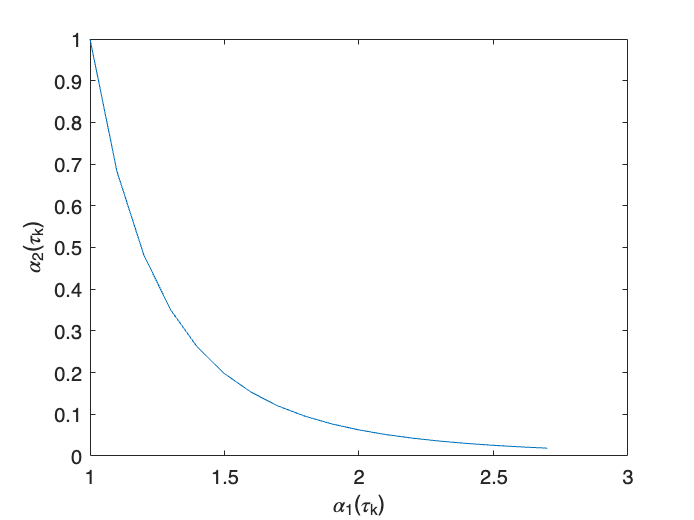

% question 4


a1 = 1:0.1:exp(1);
a2 = a1.^-4;
plot(a1,a2);
xlabel('\alpha_1(\tau_k)');  % 设置 x 轴标签
ylabel('\alpha_2(\tau_k)');  % 设置 y 轴标签


h = sym('h');
tau = sym('tau');
F = [expm(A*h) ((expm(A*h-eye(2)))/A)*B-((expm(A*(h-tau)-eye(2)))/A)*B;...
    0 0 0]

$$F = \left(\begin{array}{ccc} {\mathrm{e}}^{-4\,h} & \frac{{\mathrm{e}}^{-4\,h}}{10}-\frac{{\mathrm{e}}^{h}}{10} & \frac{{\mathrm{e}}^{4\,\tau -4\,h-1}\,\left(4\,{\mathrm{e}}^{h-\tau -1}\,{\mathrm{e}}^{4\,h-4\,\tau +1}+1\right)}{40}-\frac{{\mathrm{e}}^{-4\,h-1}\,\left(4\,{\mathrm{e}}^{h-1}\,{\mathrm{e}}^{4\,h+1}+1\right)}{40}\\ 0 & {\mathrm{e}}^{h} & {\mathrm{e}}^{h-1}-{\mathrm{e}}^{h-\tau -1}\\ 0 & 0 & 0 \end{array}\right)$$

G = [((expm(A*(h-tau)-eye(2)))/A)*B; 1]

$$G = \left(\begin{array}{c} -\frac{{\mathrm{e}}^{4\,\tau -4\,h-1}\,\left(4\,{\mathrm{e}}^{h-\tau -1}\,{\mathrm{e}}^{4\,h-4\,\tau +1}+1\right)}{40}\\ {\mathrm{e}}^{h-\tau -1}\\ 1 \end{array}\right)$$


a1 = sym('a1');
a2 = sym('a2');
e = exp(1);
F(1,3)=a1/(10*e)+a2/(40*e)-(exp(- 4*h - 1)*(4*exp(h - 1)*exp(4*h + 1) + 1))/40;
F(2,3)=exp(h - 1) - a1/e;
G(1)=-a1/(10*e)-a2/(40*e);
G(2)=a1/e;

F

$$F = \left(\begin{array}{ccc} {\mathrm{e}}^{-4\,h} & \frac{{\mathrm{e}}^{-4\,h}}{10}-\frac{{\mathrm{e}}^{h}}{10} & \frac{281474976710656\,a_{1}}{7651283143585091}+\frac{70368744177664\,a_{2}}{7651283143585091}-\frac{{\mathrm{e}}^{-4\,h-1}\,\left(4\,{\mathrm{e}}^{h-1}\,{\mathrm{e}}^{4\,h+1}+1\right)}{40}\\ 0 & {\mathrm{e}}^{h} & {\mathrm{e}}^{h-1}-\frac{2251799813685248\,a_{1}}{6121026514868073}\\ 0 & 0 & 0 \end{array}\right)$$

G

$$G = \left(\begin{array}{c} -\frac{281474976710656\,a_{1}}{7651283143585091}-\frac{70368744177664\,a_{2}}{7651283143585091}\\ \frac{2251799813685248\,a_{1}}{6121026514868073}\\ 1 \end{array}\right)$$

hs = 0.1:0.1:1.5;
spectral_radius4 = zeros(2,size(hs,2));
for j = 1:size(hs,2) 
    h=hs(j);
    a1=1;a2=1;
    F1 = double(subs(F))-double(subs(G))*[k 0];
    a1=1;a2=exp(-4*h);
    F2 = double(subs(F))-double(subs(G))*[k 0];
    a1=exp(h);a2=exp(-4*h);
    F3 = double(subs(F))-double(subs(G))*[k 0];
    eps = 0.0001;
    P = sdpvar(3,3);
    cons = [P>=eye(3)*eps,...
            (P-F1'*P*F1)>=eye(3)*eps,...
            (P-F2'*P*F2)>=eye(3)*eps,...
            (P-F3'*P*F3)>=eye(3)*eps];
    obj = 0;
    result = optimize(cons,obj);
    if result.problem==0
        spectral_radius4(1,j) = 1;
    end
    
end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 13, dim = 37, blocks = 5
nnz(A) = 87 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.68E+04 0.000
  1 :   0.00E+00 2.67E+03 0.000 0.0470 0.9900 0.9900   1.00  1  1  4.0E+01
  2 :   0.00E+00 1.27E+03 0.000 0.4771 0.9000 0.9000   0.97  1  1  2.0E+01
  3 :   0.00E+00 4.77E+02 0.000 0.3749 0.9000 0.9000   0.98  1  1  7.3E+00
  4 :   0.00E+00 9.14E+01 0.000 0.1916 0.9000 0.9000   0.99  1  1  1.4E+00
  5 :   0.00E+00 1.77E+01 0.000 0.1943 0.9000 0.9000   1.00  1  1  2.7E-01
  6 :   0.00E+00 3.39E+00 0.000 0.1913 0.9000 0.9000   1.00  1  1  5.3E-02
  7 :   0.00E+00 6.45E-01 0.000 0.1899 0.9000 0.9000   1.00  1  1  1.0E-02
  8 :   0.00E+00 1.22E-01 0.000 0.1889 0.9000 0.9000   1.00  1  1  1.9E-03
  9 :   0.00E+00 2.29E-02 0.000 0.1881 0.9000 0.9000   1.00  1  1  3.5E-04
 10 :   0.00E+00 




for j = 1:size(hs,2) 
    h=hs(j);
    a1=1;a2=1;
    F1 = double(subs(F))-double(subs(G))*[k 0];
    a1=exp(h);a2=exp(-4*h);
    F2 = double(subs(F))-double(subs(G))*[k 0];
    a1=(exp(h)-1)/2+1;a2=exp(-4*h);
    F3 = double(subs(F))-double(subs(G))*[k 0];
    a1=1;a2=((exp(h)-1)/2+1)^(-4);
    F4 = double(subs(F))-double(subs(G))*[k 0];
    eps = 0.0001;
    P = sdpvar(3,3);
    cons = [P>=eye(3)*eps,...
            (P-F1'*P*F1)>=eye(3)*eps,...
            (P-F2'*P*F2)>=eye(3)*eps,...
            (P-F3'*P*F3)>=eye(3)*eps,...
            (P-F4'*P*F4)>=eye(3)*eps];
    obj = 0;
    result = optimize(cons,obj);
    if result.problem==0
        spectral_radius4(2,j) = 1;
    end
    
end

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 16, dim = 46, blocks = 6
nnz(A) = 114 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            8.19E+04 0.000
  1 :   0.00E+00 3.40E+03 0.000 0.0415 0.9900 0.9900   1.00  1  1  4.8E+01
  2 :   0.00E+00 1.35E+03 0.000 0.3970 0.9000 0.9000   0.96  1  1  1.9E+01
  3 :   0.00E+00 2.51E+02 0.000 0.1858 0.9000 0.9000   0.99  1  1  3.6E+00
  4 :   0.00E+00 1.55E+01 0.000 0.0619 0.9900 0.9900   1.00  1  1  2.2E-01
  5 :   0.00E+00 1.02E+00 0.000 0.0655 0.9900 0.9900   1.00  1  1  1.5E-02
  6 :   0.00E+00 6.65E-02 0.000 0.0654 0.9900 0.9900   1.00  1  1  9.5E-04
  7 :   0.00E+00 4.33E-03 0.000 0.0651 0.9900 0.9900   1.00  1  1  6.2E-05
  8 :   0.00E+00 2.81E-04 0.000 0.0649 0.9900 0.9900   1.00  1  1  4.0E-06
  9 :   0.00E+00 1.82E-05 0.000 0.0647 0.9900 0.9900   1.00  1  1  2.6E-07
 10 :   0.00E+00

%question 5
Q=eye(2);
k1 = [-26,-1];
eps = 0.0001;
P = sdpvar(2,2);
cons = [P>=eye(2)*eps,...
        Q >= -((A-B*k1)'*P+P*(A-B*k1)),...
        Q <= -((A-B*k1)'*P+P*(A-B*k1))];
obj = 0;
result = optimize(cons,obj);

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3, order n = 7, dim = 13, blocks = 4
nnz(A) = 17 + 0, nnz(ADA) = 9, nnz(L) = 6
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.50E+00 0.000
  1 :   0.00E+00 7.27E-01 0.000 0.2077 0.9000 0.9000   0.37  1  1  2.2E+00
  2 :   0.00E+00 1.63E-01 0.000 0.2243 0.9000 0.9000  -0.60  1  1  1.5E+00
  3 :   0.00E+00 3.55E-02 0.000 0.2178 0.9000 0.9000   0.42  1  1  3.4E-01
  4 :   0.00E+00 1.44E-03 0.000 0.0404 0.9900 0.9900   1.21  1  1  1.2E-02
  5 :   0.00E+00 2.97E-06 0.000 0.0021 0.9990 0.9990   1.02  1  1  2.5E-05
  6 :   0.00E+00 3.06E-09 0.000 0.0010 0.9999 0.9999   1.00  1  1  2.6E-08
  7 :   0.00E+00 3.15E-12 0.000 0.0010 0.9999 0.9999   1.00  2  2  2.6E-11

iter seconds digits       c*x               b*y
  7      0.1   Inf -9.8582289259e-13  0.0000000000e+00
|Ax-b| =   7.2e-12, [Ay-c]_+ =   5.4E-12, |x|=  1.1e+01, |y|=  3.5

P=double(P);


havg = 10/(401+501+524)

havg = 0.0070

sys = ss(A,B,[1 1],0);
sysd = c2d(sys, havg);
max(abs(eig(sysd.A-sysd.B*k1)))

ans = 0.9931